# Problema 5

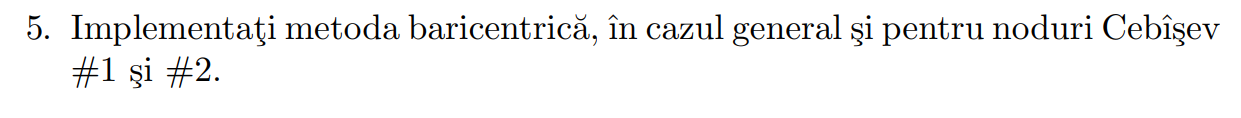

**Ce este interpolarea baricentrică?**

Interpolarea baricentrică este o metodă eficientă pentru construirea polinomului de interpolare Lagrange, dar într-o formă numerically stabilă și rapidă.

Spre deosebire de formula clasică a lui Lagrange, care implică multe produse și este sensibilă la erori numerice, forma baricentrică utilizează **ponderi precomputate** (numite **ponderi baricentrice**) care simplifică calculul și evită problemele de stabilitate.

**De ce o folosim?**

- Este mai **rapidă** decât forma clasică.

- Este **mai precisă**, mai ales când numărul de noduri crește.

- Este **ideală pentru implementare numerică** (MATLAB, NumPy, etc.).

- Permite evaluarea eficientă a interpolantului chiar și în puncte apropiate de noduri.

**Noduri Chebyshev de ordinul I și II**

Pentru a îmbunătăți și mai mult interpolarea, folosim **noduri Chebyshev** în locul nodurilor echidistante. Acestea sunt distribuite mai dens la capetele intervalului și ajută la:

- Reducerea erorii de interpolare,

- Prevenirea fenomenului Runge (oscilații mari la margini),

- Obținerea unui polinom care aproximează mai bine funcția reală.

Există două tipuri:

        Noduri Chebyshev de ordinul I

                $x_i =\cos \left(\frac{2i+1}{2n}\pi \right),i=1,2,\ldotp \ldotp ,n$. Sunt cele mai folosite în interpolarea baricentrică.

        Noduri Chebyshev de ordinul II

                $x_i =\cos \left(\frac{j\pi }{n-1}\right),j=1,2,\ldotp \ldotp ,n$. Au avantajul că includ capetele intervalului și sunt utilizate în unele aplicații speciale.

function x = genereazaNoduriChebyshev(n, a, b, tip)
% INPUT:
%   n   - numarul de noduri
%   a,b - capetele intervalului
%   tip - 'I' pentru Chebyshev de tip I, 'II' pentru tip II
%
% OUTPUT:
%   x   - vector cu nodurile generate

    switch tip
        case 'I'
            % Noduri Chebyshev de ordinul I (nu includ capetele intervalului)
            j = 0:n-1;
            x = cos((2*j + 1)*pi/(2*n));
        case 'II'
            % Noduri Chebyshev de ordinul II (includ capetele intervalului)
            j = 0:n-1;
            x = cos(j*pi/(n-1));
        otherwise
            error('Tip invalid. Foloseste ''I'' sau ''II''.');
    end

    % Reproiectare a nodurilor din intervalul [-1, 1] in [a, b]
    x = ((b - a)/2) * x + (a + b)/2;
end


function w = calculeazaPonderiBaricentrice(x_noduri)
% CALCULEAZAPONDERIBARICENTRICE - Calculeaza ponderile baricentrice pentru interpolare
%
% INPUT:
%   x_noduri - vector cu nodurile de interpolare
%
% OUTPUT:
%   w        - vector cu ponderile baricentrice

    n = length(x_noduri);  % numarul de noduri
    w = ones(1, n);         % initializare ponderi cu 1

    % Calculul fiecarei ponderi w(j)
    for j = 1:n
        for k = [1:j-1, j+1:n]  % evitam cazul k = j
            w(j) = w(j) / (x_noduri(j) - x_noduri(k));  % produsul inverselor distantelor
        end
    end
end

function [p, p_expr] = interpolareBaricentricaExtinsa(x_noduri, y_noduri, w, x_eval)
% INTERPOLAREBARICENTRICAEXTINSA - Interpolare baricentrica + forma simbolica + coeficienti
%
% INPUT:
%   x_noduri  - nodurile de interpolare (vector)
%   y_noduri  - valorile functiei in noduri
%   w         - ponderile baricentrice calculate anterior
%   x_eval    - punctele in care vrem sa evaluam interpolantul
%
% OUTPUT:
%   p         - vectorul valorilor interpolate
%   p_expr    - polinomul exprimat simbolic (obtinere cu Lagrange clasic)

    % Initializam vectorul de rezultate p cu zerouri
    p = zeros(size(x_eval));

    % Evaluam interpolarea baricentrica in fiecare punct din x_eval
    for k = 1:length(x_eval)
        x = x_eval(k);  % punctul curent

        % Daca x coincide exact cu un nod de interpolare, returnam valoarea functiei
        idx = find(abs(x - x_noduri) < 1e-14, 1);
        if ~isempty(idx)
            p(k) = y_noduri(idx);
            continue;
        end

        % Calculam termenii baricentrici
        termen = w ./ (x - x_noduri);
        % Evaluam valoarea interpolata ca raport de sume
        p(k) = sum(termen .* y_noduri) / sum(termen);
    end

    % ==== CONSTRUCTIA POLINOMULUI SIMBOLIC (LAGRANGE CLASIC) ====

    syms x;             % definim simbolul x
    n = length(x_noduri); 
    p_expr = 0;         % initializam expresia polinomului cu 0

    % Construim fiecare baza de interpolare L_j(x)
    for j = 1:n
        Lj = 1;  % baza de interpolare pentru nodul j

        % Produsul celorlalti termeni pentru L_j(x)
        for k = [1:j-1, j+1:n]
            Lj = Lj * (x - x_noduri(k)) / (x_noduri(j) - x_noduri(k));
        end

        % Adaugam termenul y_j * L_j(x) in polinomul final
        p_expr = p_expr + y_noduri(j) * Lj;
    end

    % Expandam expresia simbolica pentru a obtine forma dezvoltata
    p_expr = expand(p_expr);
end


% Functia de interpolat
f = @(x) 1 ./ (1 + 25 * x.^2);

% Interval si numar de noduri
a = -1;
b = 1;
n = 11;

% ==== Chebyshev I ====
x_noduri_I = genereazaNoduriChebyshev(n, a, b, 'I');
y_noduri_I = f(x_noduri_I);
w_I = calculeazaPonderiBaricentrice(x_noduri_I);
x_eval = linspace(a, b, 500);
[p_I, p_expr_I] = interpolareBaricentricaExtinsa(x_noduri_I, y_noduri_I, w_I, x_eval);

% ==== Chebyshev II ====
x_noduri_II = genereazaNoduriChebyshev(n, a, b, 'II');
y_noduri_II = f(x_noduri_II);

Polinomul simbolic Chebyshev I:


w_II = calculeazaPonderiBaricentrice(x_noduri_II);

                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                           10                                                                                                                                                                                                                                                                           

[p_II, p_expr_II] = interpolareBaricentricaExtinsa(x_noduri_II, y_noduri_II, w_II, x_eval);


Polinomul simbolic Chebyshev II:


% ==== Afisare rezultate ====

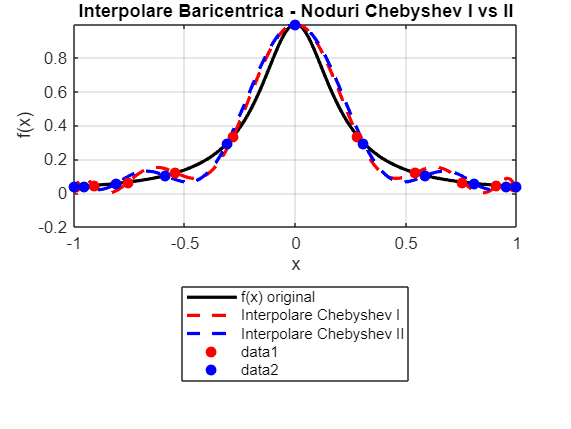

disp('Polinomul simbolic Chebyshev I:');
pretty(p_expr_I)

disp('Polinomul simbolic Chebyshev II:');
pretty(p_expr_II)


% ==== Grafic comparativ ====
figure;
plot(x_eval, f(x_eval), 'k-', 'LineWidth', 2, 'DisplayName', 'f(x) original');
hold on;
plot(x_eval, p_I, 'r--', 'LineWidth', 2, 'DisplayName', 'Interpolare Chebyshev I');
plot(x_eval, p_II, 'b--', 'LineWidth', 2, 'DisplayName', 'Interpolare Chebyshev II');
plot(x_noduri_I, y_noduri_I, 'ro', 'MarkerFaceColor', 'r');

plot(x_noduri_II, y_noduri_II, 'bo', 'MarkerFaceColor', 'b');
legend('Location', 'southoutside');
title('Interpolare Baricentrica - Noduri Chebyshev I vs II');
xlabel('x'); ylabel('f(x)');
grid on;